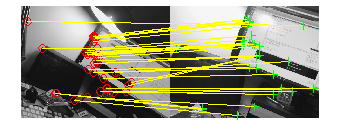

% Q3
original = rgb2gray (imread('I2.jpg'));
distorted = rgb2gray (imread('I3.jpg'));

ptsOriginal = detectSURFFeatures(original);
ptsDistorted = detectSURFFeatures(distorted);
[featuresOriginal, validPtsOriginal] = extractFeatures(original,ptsOriginal);
[featuresDistorted, validPtsDistorted] = extractFeatures(distorted,ptsDistorted);

indexPairs = matchFeatures(featuresOriginal,featuresDistorted);
matchedOriginal = validPtsOriginal(indexPairs(:,1));
matchedDistorted = validPtsDistorted(indexPairs(:,2));

figure;
showMatchedFeatures(original,distorted,matchedOriginal,matchedDistorted,'montage');

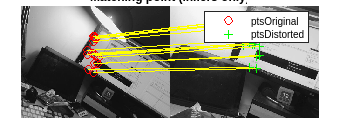


[tform,inlierDistorted,inlierOriginal] = estimateGeometricTransform (matchedDistorted,matchedOriginal,'similarity');

figure;
showMatchedFeatures(original,distorted,inlierOriginal,inlierDistorted,'montage');
title('Matching point (inliers only)');
legend ('ptsOriginal','ptsDistorted');


Tinv = tform.invert.T;
ss = Tinv(2,1);
sc = Tinv(1,1);
scaleRecovered = sqrt(ss*ss+sc*sc);
thetaRecovered = atan2(ss,sc)*180/pi;

ShowTheWay(thetaRecovered);

Error using plot3
Vectors must be the same length.

Error in ShowTheWay (line 14)
plot3(xt,yt,zt);


outputView = imref2d(size(original));
recovered = imwarp(distorted,tform,'OutputView',outputView);
figure;
imshowpair(original,recovered,'montage');